# Actividad #9

#### Fecha: 28/06/2024

#### Objetivos:

- Crear funciones : fLoadCSV.m

- Usar matrices de 3 dimnesiones (muestras, variables, clientes)

- Cambio de clientes con controles para mostrar datos

- Ejemplos adicionales: horzcat, vertcat, ampliar matrices

#### Nombre:

- sunombre

#### Repository:

- [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

#### Librarys:

- [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

## Paso 1: Limpiar variables y linea de comandos

clear % Para borrar el workspace y liberar memoria RAM
clc  % Limpiar el command window
raiz = cd;%Linux: Addres Current folder

## Paso 2.- Configuración de carpeta ./src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

## **Paso 3- Configuranción de carpeta de ./data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');

## **Paso 4- Buscar los nombres y **Cargar los datos **de todos los archivos dentro de la carpeta ./data**

%Nombre de la carpeta donde estan los archvios csv

%Obtener los nombres de las carpetas
% Se asume que solo hay carpetas
cd(datapath); %Matlab: Acceder a la carpeta llamada del data
FolderNames=ls; %Linux: enlista todos las carpetas y archivos
cd(raiz);% "cd .." return to initial current folder
FolderNames=FolderNames(3:size(FolderNames,1),:);%Elimina ".", ".."


%AllData=NaN(5628,5,size(FolderNames,1));%Analizarlo NaN
AllData=[];

for i=1:1:size(FolderNames,1) %# de filas = # de carpetas
    names=FindCSV(fullfile(datapath,FolderNames(i,:)));
    %filenames=[filenames struct2table(names).name];
    newPath=strcat(fullfile(datapath,FolderNames(i,:)),'\');
    AllData(:,:,i)= fLoadCSV(names,newPath);
end
MaxClient=size(AllData,3);

## Paso 5: Set de Nombres de variables

Es importante que el archivo csv se encuentre en la misma carpeta que el main

%AllData = fLoadCSV(filenames,datapath);

%maxfilas=length(AllData);%Maximo numero de filas
%Estos son los nombres de las variables
vname=["Corriente","Voltaje","variable3","variable4","variable5"];
clear Dataset filenames i

## Paso 6: Graficar el dataset

Seleccionar el numero de variables a mostrar


nvar=5;
nfilas=10;
Cliente=4;

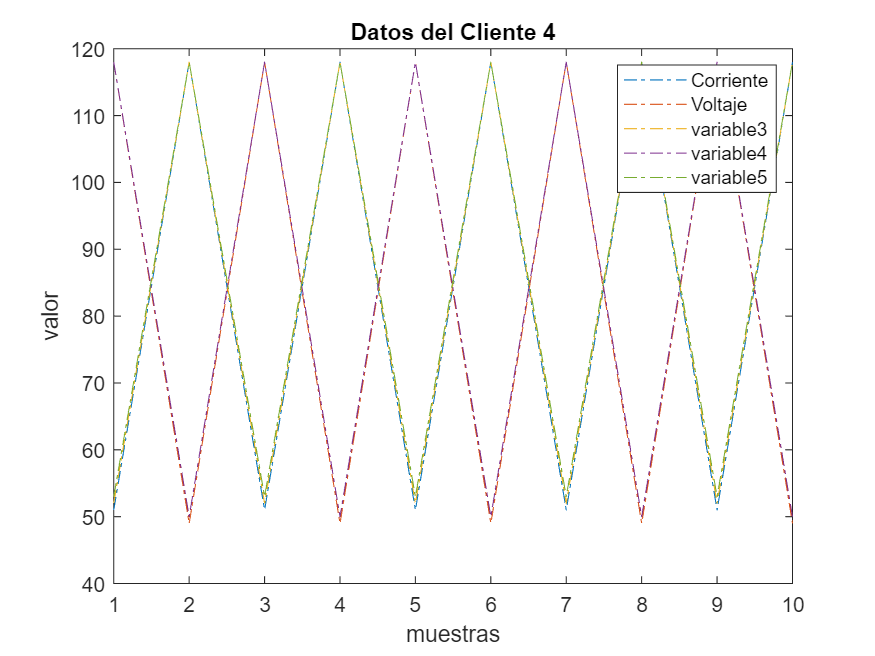

figure %no sobrescribe la anterior grafica
plot(AllData(1:nfilas,1:nvar,Cliente),'-.');%
title(sprintf("Datos del Cliente %d", Cliente));
xlabel("muestras");
ylabel("valor");
legend(vname(1:nvar))

## Ejemplos adicionales:

Use de length y size en Vectores

V1=[1:10];
V2=V1';

%Length
nElementsv1=length(V1)

nElementsv1 = 10

nElementsv2=length(V2)

nElementsv2 = 10

%Size
filasV1=size(V1,1)

filasV1 = 1

filasV2=size(V2,1)

filasV2 = 10


columnasV1=size(V1,2)

columnasV1 = 10

columnasV2=size(V2,2)

columnasV2 = 1

Use de length y size en Matrices

A=[1:5;2:6;3:7];
B=A';
%Length
nElementsA=length(A)

nElementsA = 5

nElementsB=length(B)

nElementsB = 5

%Size
sizeA=size(A)

sizeA =      3     5


sizeB=size(B)

sizeB =      5     3



filasA=size(A,1)

filasA = 3

filasB=size(B,1)

filasB = 5


columnasA=size(A,2)

columnasA = 5

columnasB=size(B,2)

columnasB = 3

Apliar una matrix y concatenar por filas, Version 1

D1=[1:5;2:6]%5 variables

D1 =      1     2     3     4     5
     2     3     4     5     6


D2=[1:2;2:3]%2 variables

D2 =      1     2
     2     3



DZ=zeros(size(D1,1),size(D1,2)-size(D2,2))

DZ =      0     0     0
     0     0     0


%D2=[D2 DZ]
D2=[D2,DZ]

D2 =      1     2     0     0     0
     2     3     0     0     0


%D2=horzcat(D2,DZ)

DT=[D1;D2]

DT =      1     2     3     4     5
     2     3     4     5     6
     1     2     0     0     0
     2     3     0     0     0


%DT=vertcat(D2,D2)

Apliar una matrix y concatenar por filas, Version 2

D1=[1:5;2:6]%5 variables

D1 =      1     2     3     4     5
     2     3     4     5     6


D2=[1:3;2:4]%2 variables

D2 =      1     2     3
     2     3     4



D2(1,size(D1,2))=0

D2 =      1     2     3     0     0
     2     3     4     0     0



DT=[D1;D2]

DT =      1     2     3     4     5
     2     3     4     5     6
     1     2     3     0     0
     2     3     4     0     0


Apliar una matrix y concatenar por filas, Version 3

D1=[1:5;2:6]%5 variables

D1 =      1     2     3     4     5
     2     3     4     5     6


D2=[1:3;2:4]%2 variables

D2 =      1     2     3
     2     3     4



if size(D1,2)>size(D2,2)
    D2(1,size(D1,2))=0
elseif size(D1,2)<size(D2,2)
    D1(1,size(D2,2))=0
end

D2 =      1     2     3     0     0
     2     3     4     0     0



DT=[D1;D2]

DT =      1     2     3     4     5
     2     3     4     5     6
     1     2     3     0     0
     2     3     4     0     0
